data = importdata('ROC_REAL_50.mat');

**1.a)** Selecionamos da base de dados 10 pacientes:

% Definimos uma seed estatica para o gerador de números aleatórios de forma
% a podermos repetir os experimentos com os mesmos resultados
rng(42);
rndIDX = randperm(50);
sample = data(rndIDX(1:10), :)

sample =     0.0219    1.2746
    0.0528    2.5362
    0.0352    1.5503
    0.0293    1.4728
    0.0308    1.9499
    0.0330    2.4823
    0.0282    1.2615
    0.0295    1.2390
    0.0329    2.5669
    0.0394    2.0425


**1.b)**

Representação de $c_e \left(t\right)$

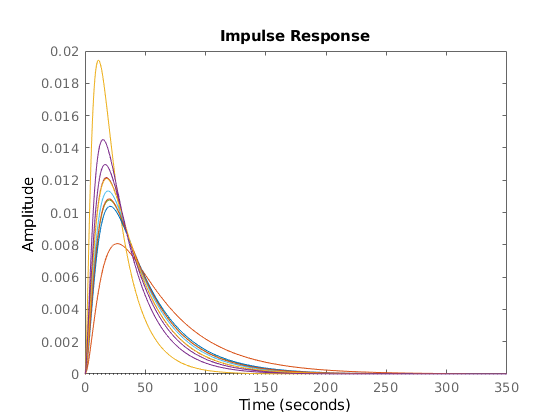

figure(1)
hold on
Ce = [];
for row = 1 : length(sample)
    a = sample(row,1);
    s = tf('s');
    G = (40*a^3)/((s+a)*(s+4*a)*(s+10*a));
    % Plot
    impulse(0.6*G)
    % Save the data
    Ce = [Ce, impulse(0.6*G)];
    
end
hold off

Ce = Ce(2:end,:);

Representação de $r\left(t\right)$

r0 = 1

r0 = 1

EC50 = 1

EC50 = 1

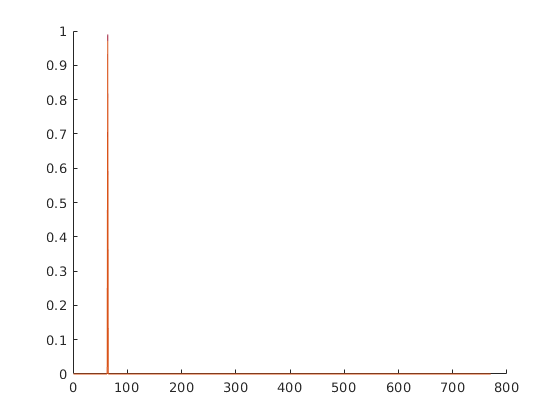

figure(2)
hold on

for row = 1 : length(sample)
    gama = sample(row,2);
    R = r0 / (1 + (Ce(row, :) / EC50) * gama);
    plot(R)
end

Error using  / 
Matrix dimensions must agree.

hold off